# Orbital-Free Density Functional Theory

## **Beyond Thomas-Fermi Approximation**

Density Functional Theory (DFT) is based on representing energy of interacting $N$-electron quantum-mechanical system as a functional of electron density $\rho(\mathbf{r})$, $E[\rho]=T[\rho]+V_{ee}[\rho ]+ \int \rho (\mathbf{r})  V_{ext}(\mathbf{r}) d \mathbf{r}$, so that the ground state enery is $E_0=E[\rho_0]=\mathrm{min}\{ E[\rho]\}$, where $\rho_0(\mathbf{r})$ is the ground state electron density. **Orbital-free (or pure) DFT** (OFDFT) is the direct implementation of DFT, following the original spirit of Thomas-Fermi and Hohenberg-Kohn, where the energy functional of interacting electron system can be cast in terms of the electron density $\rho(\mathbf{r})$ alone. To do this, we need to adopt some approximate expressions for the universal functionals $T[\rho]$ and $V_{ee}[\rho]$. 

We will implement OFDFT for interacting electrons having spherically symmetric ground state electron density. Similar to Thomas-Fermi model, we will study here neutral atoms with nuclear charge $Z$ (with immobile nucleus in the Born-Oppenheimer approximation) and with filled subshells. 

For a neutral atom, with atomic number $Z$, in the limit of $Z\to \infty$ [exact](https://journals.aps.org/prl/abstract/10.1103/PhysRevLett.31.681) $E[\rho]$ is given by the Thomas-Fermi (TF) energy functional, 


$$E[\rho]=T_{TF}[\rho]-Z\int \frac{\rho(\mathbf{r})}{|\mathbf{r}|}  d \mathbf{r} + \frac{1}{2} \int\int \frac{\rho\left(\mathbf{r}\right) \rho\left(\mathbf{r'}\right)}{\left|\mathbf{r'}-\mathbf{r}\right|} d \mathbf{r} d \mathbf{r'}.$$


Expression of the TF kinetic energy functional $T_{TF}[\rho]$ is given in Eq. (2) below. Electron-electron repulsion in the TF model is only accounted by the Hartree or direct interaction energy functional, that includes unphysical self-interaction of electrons. 

For atoms with finite $Z$, expression of the kinetic energy functional $T[\rho]$ is unknown. Moreover there is an additional universal functional beyond the Hartree term that is called exchange-correlation (xc) energy functional and is usually written as $E_{xc}[\rho]=\int  \epsilon_{x c}[\rho](\mathbf {r}) \rho(\mathbf{r}) d \mathbf{r}$, where the xc energy per electron 

$\epsilon_{xc}[\rho](\mathbf{r})=\displaystyle \frac{\delta E_{xc}[\rho]}{\delta \rho (\mathbf{r})}-\frac{1}{2!}\int \frac{\delta^2  E_{xc}[\rho]  } {\delta \rho(\mathbf{r})\delta \rho(\mathbf{r'})   } \rho(\mathbf{r'}) d\mathbf{r'}+ \frac{1}{3!}\int \frac{\delta^3  E_{xc}[\rho]  } {\delta \rho(\mathbf{r})\delta \rho(\mathbf{r'})  \delta \rho(\mathbf{r''})   } \rho(\mathbf{r'}) \rho(\mathbf{r''}) d\mathbf{r'}d\mathbf{r''}+\cdots$.

$\epsilon_{x c}[\rho](\mathbf{r})$ can show arbitrarily complicated, non-local dependence on electron density, its gradient, etc. Exact energy functional of electron density for finite-$Z$ atom, without further specifying the universal expressions of $T[\rho]$ and $\epsilon_{xc}[\rho](\mathbf{r})$, is written as:


$$E[\rho]=T[\rho]-Z\int \frac{\rho(\mathbf{r})} {|\mathbf{r}|} d \mathbf{r}+\frac{1}{2} \int \int  \frac{\rho(\mathbf{r}) \rho\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|}d \mathbf{r} d \mathbf{r}^{\prime}+\int  \epsilon_{x c}[\rho](\mathbf {r}) \rho(\mathbf{r}) d \mathbf{r}.$$


OFDFT is an extension of the TF model with additional terms to correct both the kinetic energy as well as the electron-electron interaction energy functionals. 

### von Weizsäcker Correction

The accuracy of OFDFT calculations heavily depends primarily on the quality of approximate kinetic energy functional. Among the most popular forms for kinetic energy density functionals (KEDFs) is one that is built out of 2 parts with a mixing parameter $\lambda$:


$$\begin{array}{cc}T[\rho]=T_{\mathrm{TF}}[\rho]+\lambda T_{\mathrm{vW}}[\rho].& \qquad (1)\\ \end{array}$$
 

$T_{\mathrm{TF}}$ is the TF kinetic energy functional,


$$\begin{array}{cc}T_{\mathrm{TF}}[\rho]=C_F \int \rho^{5 / 3}(\mathbf{r})d \mathbf{r},& \qquad (2)\\ \end{array}$$


with $C_F = \frac{3}{10}\left(3 \pi^2\right)^{2 / 3}$ being a numerical factor in [Hartree system of atomic units](https://en.wikipedia.org/wiki/Hartree_atomic_units) that we have adopted here. $T_{\mathrm{vW}}$ is the semilocal [von Weizsäcker functional](http://przyrbwn.icm.edu.pl/APP/PDF/115/a115z310.pdf) accounting for an inhomogeneity correction,


$$T_{\mathrm{vW}}[\rho] =\frac{1}{2} \int \Big(\nabla \sqrt{\rho(\mathbf{r})} \Big)^2 d \mathbf{r} =\frac{1}{8} \int \frac{ \Big(\nabla \rho(\mathbf{r}) \Big)^2 }{\rho (\mathbf{r})}d \mathbf{r} \\ \qquad  \quad = \frac{1}{2}\int \Big(\nabla \xi(\mathbf{r})\Big)^2 d \mathbf{r}  = -\frac{1}{2}\int \xi(\mathbf{r}) \nabla^2 \xi(\mathbf{r}) d \mathbf{r}, \qquad (3)$$


where $\xi = \sqrt{\rho}$ . In this form, the total energy functional of OFDFT is:


$$\begin{array}{cc}\begin{array}{rll}E[\rho]=& C_F \int \rho^{5 / 3}(\mathbf{r})d \mathbf{r} + \frac{\lambda}{2}\int\Big(\nabla \xi(\mathbf{r})\Big)^2 d \mathbf{r}  \\&-\int \rho(\mathbf{r}) \frac{Z}{|\mathbf{r}|} d \mathbf{r}+\frac{1}{2} \int \int  \frac{\rho(\mathbf{r}) \rho\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|}d \mathbf{r} d \mathbf{r}^{\prime}+\int \epsilon_{x c}[\rho](\mathbf {r}) \rho(\mathbf{r})d \mathbf{r} . \end{array}& \qquad (4)\\ \end{array}$$


We will treat $\lambda$ as a freely adjustable parameter $0\le \lambda \le 1$; von Weizsäcker obtained $\lambda=1$. Later it was suggested that the value of $\lambda=1/9$ is more appropriate for certain systems. In our numerical implementation of radial OFDFT, $\lambda \sim 1/5$ (in agreement with Ref. [2]) seems optimal choice for calculating ground state energies for system sizes of $N_d$ between $2000-8000$ sites and $R_{max}=60/Z^{1/3}$. For $N_d=8000$ we get accuracy of $\sim 1\%$ or better when comparing our results with the [reported ground state energies](https://en.wikipedia.org/wiki/Ionization_energies_of_the_elements_(data_page)) for atoms with $Z>1$ (better accuracy we get for lower values of $Z$, however many larger values of $Z$ agree within $\sim 1\%$ with the reported results, e.g. for chromium with $Z=24$ reported value is $E_0=-28585 eV$, whereas we obtain for $N_d=10,000$: $E_0=-28383eV$). The accuracy for the ground state electron densities $4\pi \rho(r) r^2$, however, obtained in our OFDFT simulations is poor for any $Z$, despite the fact that inclusion of $\lambda$ and xc terms improve TF result. In particular we do not recover additional bumps in radial electron density $\int \rho(\mathbf{r}) r^2\sin{\theta} d\theta d\phi$, reflecting shell structure of atoms, see section Radial Electron Density in Shell Model in live script *Hydrogen Atom*.

### Local Density Approximation to Exchange-Correlation Functional

For the last term in the energy functional Eq. (4) we will use local density approximation ([LDA](https://en.wikipedia.org/wiki/Local-density_approximation)), where we assume that $\epsilon_{xc}[\rho](\mathbf{r})$ depends on $\mathbf{r}$ only through local $\rho(\mathbf{r})$: $E_{xc}[\rho]=\int \epsilon_{x c}(\rho(\mathbf {r})) \rho(\mathbf{r})d \mathbf{r}$. LDA plays similar role for xc functional, as $T_{TF}[\rho]$ in Eq. (2) plays for kinetic energy functional. In the following we will adopt a particular version of LDA, known as a LDA-PZ approximation. We write xc per electron as a sum of exchange and correlation terms $\epsilon_{xc}=\epsilon^{LDA}_{x}+\epsilon^{LDA-PZ}_{c}$. The first term $\epsilon_{x}^{LDA}(\rho)$ is obtained from the ground state exchange energy per electron of a [homogenous electron gas](https://en.wikipedia.org/wiki/Jellium) (HEG or so called jellium model is a gas of interacting electrons with uniformly distributed positive background charge, keeping overall charge neutrality of the system) of charge density $\rho$ and its expression is known analytically for any $\rho$ [*]. HEG is a key starting model in the construction of many xc functionals used in DFT [2]. 

Exchange contribution in HEG: $\epsilon_{x}^{HEG}(\rho_0)=-\frac{3}{4} \Big(  \frac{3}{\pi} \rho_0 \Big)^{1/3}$. This expression is obtained for the case of uniform ground state electron density of HEG. For the case of non-uniform density, following [Dirac](https://www.cambridge.org/core/journals/mathematical-proceedings-of-the-cambridge-philosophical-society/article/note-on-exchange-phenomena-in-the-thomas-atom/6C5FF7297CD96F49A8B8E9E3EA50E412), we will assume that similar expression holds, but with local density $\rho(\mathbf{r})$ instead of $\rho_0=N/V$ 


$$\epsilon_{x}^{LDA}(\rho(\mathbf{r}))=-\frac{3}{4} \Big(  \frac{3}{\pi} \rho (\mathbf{r}) \Big)^{1/3},$$


assumption known under LDA. 

For the second, correlation term, that is defined as a mismatch between exact complete potential energy of HEG and Hartree-Fock exchange-only contribution, only the limiting expressions are known analytically for $\rho \to 0$ (low density, where itinerant ferromagnetism and Wigner crystalization are expected) and $\rho \to \infty$ (high density, kinetic energy dominated paramagnetic Fermi fluid) limits. For the intermediate densities, based on quantum Monte-Carlo simulations, different interpolation schemes have been suggested in the beginning of the 1980s. In fact DFT became popular approach due to availability of practical exchange-correlation functionals from quantum Monte-Carlo calculations. We will implement the Perdew-Zunger correlation expression, one of the most popular LDA implementations, LDA-PZ:  


$$\epsilon_c^{LDA-PZ} (\rho(\mathbf{r}))=  \begin{cases}   -0.048+0.031\ln r_s(\mathbf{r})-0.00116r_s(\mathbf{r})+0.002r_s(\mathbf{r})\ln r_s(\mathbf{r}) ,& \text{if } r_s< 1 \,(\mathrm{high\, density\, limit})\\  -0.1432/\left(1+1.0529\sqrt{r_s(\mathbf{r})} +0.3334r_s(\mathbf{r})\right), &  \text{if }  r_s\ge 1 \,(\mathrm{low\, density\, limit}).\end{cases}$$


The [Wigner-Seitz radius](https://en.wikipedia.org/wiki/Wigner%E2%80%93Seitz_radius) $r_s(\mathbf{r})=(3/(4\pi \rho(\mathbf{r})))^{1/3}$, radius of effective sphere around an electron, is a dimensionless number, as any length scale in atomic units (measured in Bohr radius units) and $r_s\ll 1$corresponds to the high-density or weakly-correlated regime where kinetic energy of the electrons dominates their mutual Coulomb repulsion potential energy. By definition, the correlation term is not accounted for in Hartree-Fock approach, when many-body wave function is represented as a single Slater determinant of single-electron wave functions. 

Since the contribution from the kinetic energy (given in the first line of Eq. (4)) in the total energy of electrons is crucial, the accurate approximation in kinetic energy directly results in reliable total energy calculation. The difficulty to develop general-purpose KEDF remains one of the main limitations of OFDFT. Kohn-Sham (orbital) formulation of DFT covered in another live script was developed for this very problem that OFDFT has.

## Euler-Lagrange Equation for OFDFT 

As in the case of the Thomas-Fermi model (covered in live script *Thomas-Fermi Approximation*), to minimize the total energy under the constraint imposed on electron density $\int \rho(\mathbf{r})d\mathbf{r} =N$, similar to the TF model the Lagrange functional of the OFDFT with Lagrange multiplier $\mu$ (chemical potential) is considered (and as usual constraint is implemented by $\partial {\cal L} /\partial \mu=0$)


$$\begin{array}{cc}\mathcal{L}[\rho] = E[\rho] - \mu \left(\int \rho(\mathbf{r}) d \mathbf{r}-N\right).& \qquad (5)\\ \end{array}$$


By taking [functional derivative](https://en.wikipedia.org/wiki/Functional_derivative) of $\mathcal{L}$ with respect to $\xi(\mathbf{r}) = \sqrt{\rho(\mathbf{r})}$ and putting it to zero and using $\frac{\delta \mathcal{L}}{\delta \xi(\mathbf{r})} = 2\xi(\mathbf{r} ) \frac{\delta \mathcal{L}}{\delta \rho(\mathbf{r})}$, we obtain 


$$\begin{array}{cc}2\hat \mathcal{H} \xi(\mathbf{r})=2\mu \xi(\mathbf{r}), \quad \hat\mathcal{H}=-\frac{\lambda}{2} \nabla^2+V_{\mathrm{TF}}(\mathbf{r})+V_{\mathrm{ext}}(\mathbf{r}) +V_{\mathrm{H}}(\mathbf{r})+ V_{\mathrm{xc}}(\mathbf{r}),& \qquad (6)\\ \end{array}$$


where


$$\begin{array}{cc}V_{\mathrm{TF}}[\rho](\mathbf{r})=\frac{5}{3} C_F \rho^{2/3}(\mathbf{r}), \quad V_{\mathrm{ext}}(\mathbf{r}) = -\frac{Z}{|\mathbf{r}|}, \quad V_{\mathrm{H}}[\rho](\mathbf{r}) = \int  \frac{\rho\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|}d \mathbf{r}^{\prime},& \qquad (7)\\ \end{array}$$
 

and

 
$$V_{\mathrm{xc}}[\rho](\mathbf{r}) = \frac{\delta \int \epsilon_{\mathrm{xc}}(\rho(\mathbf{r'}))  \rho(\mathbf{r'})  d\mathbf{r'} }{\delta \rho(\mathbf{r})}=\epsilon_{\mathrm{xc}}(\rho(\mathbf{r})) +  \int \frac{ \delta \epsilon_{\mathrm{xc}}(\rho(\mathbf{r'}))}{\delta \rho(\mathbf{r})}  \rho(\mathbf{r'})d\mathbf{r'} . \qquad (7b)$$


In this note, we use the LDA-PZ exchange correlation throughout, $\epsilon_{xc}(\rho (\mathbf{r})) = \epsilon^{LDA}_{xc}(\rho (\mathbf{r})) =\epsilon_x^{LDA}(\rho(\mathbf{r}))+\epsilon_c^{LDA-PZ}(\rho(\mathbf{r}))$. 

For LDA we have: $V^{LDA}_{xc}[\rho] (\mathbf{r}) = \frac{d}{d\rho} (\rho \epsilon^{LDA}_{xc})(\mathbf{r})$. 

We  obtain the Hartree potential $V_{\mathrm{H}}$ by solving the Poisson's equation


$$\begin{array}{cc}\nabla^2 V_{\mathrm{H}}(\mathbf{r})=-4\pi\rho(\mathbf{r}).& \qquad (8)\\ \end{array}$$


Eq. (8) is a standard relation between the electric potential and electric charge density at a point $\mathbf{r}$ and follows from the definition of $V_H$ (the right-most term in Eqs. (7)) and the following relation: $\nabla^2 (1/|\mathbf{r} -\mathbf{r'}|)=-4\pi \delta^3(\mathbf{r}-\mathbf{r'})$. In Exercise 1 we suggest reader to show from the last equation in Eqs. (7) in case of spherically symmetric charge distribution, when $\rho(\mathbf{r})=\rho(r )$, Hartree potential $V_{\mathrm{H}}[\rho](\mathbf{r})$ alslo has spherical symmetry.

We showed in live script *Thomas-Fermi Approximation* that for $\lambda$=0 and without xc contribution, for neutral atoms for any $Z$, the chemical potential $\mu=0$ and the Euler-Lagrange equation for $\rho$ (the Thomas-Fermi equation for neutral atom $\rho_{TFNA}$) had a unique solution. Note, even though Eq. (6)  (or rather its 1D implementation Eq. (12)) looks like eigen value equation that may have infinite number of solutions, restriction of non-negativity $\xi(\mathbf{r}) = \sqrt{\rho(\mathbf{r})}\ge 0$ filters out a unique solution, see Exercise 6. In one dimension, the ground state of the Schrödinger equation can be [proven to have no nodes](https://en.wikipedia.org/wiki/Ground_state). In order to be orthogonal to the ground state, all excited states must necessarily have nodes, proving uniqueness of eigen state of Eq. (12) with $\xi(\mathbf{r}) \ge 0$. 

We will implement non-linear conjugate gradient method to minimize Lagrange functional in Eq. (5) iteratively, starting from the TF density (or some other trial density). Density normalization, following from $\partial {\cal L}/\partial \mu=0$, will be kept throughout the iterations. Energy will be calculated from Eq. (4), and chemical potential will be calculated from: $\mu = \frac{4\pi}{Z}\int u(r) \hat \mathcal{H}_ru(r) dr$, where $u(r )=r\sqrt{\rho( r)}$ and $\hat \mathcal{H}_r$ is written below in Eq. (12). 

### Radial OFDFT

For systems with spherically symmetric ground state electron density, e.g. single atom with filled subshells, we can derive simplified version of Eq. (6): the radial equation for OFDFT. We start from the following representations:


$$\begin{array}{cc}\rho(\mathbf{r})=\rho(r), \quad     \xi(\mathbf{r})=\xi(r),& \qquad (9)\\ \end{array}$$
 

where $r = |\mathbf{r}|$. In spherical coordinates, if a function $f$ has spherical symmetry, i.e. $f(\mathbf{r})=f(r)$, the Laplacian of such function is (for $r>0$, avoiding the singular 3D Dirac's delta-function contribution at $r=0$)


$$\begin{array}{cc}\nabla^2 f=\frac{1}{r^2} \frac{\partial}{\partial r}\left(r^2 \frac{\partial f}{\partial r}\right) = \frac{1}{r} \frac{\partial^2}{\partial r^2}(r f).& \qquad (10)\\ \end{array}$$
 

Introducing variable


$$\begin{array}{cc}u (r ) = r\xi(r)& \qquad (11)\\ \end{array}$$
 

Eq. (6) becomes


$$\begin{array}{cc}\hat\mathcal{H}_r u(r)=\mu u(r), \quad \hat \mathcal{H}_r=-\frac{\lambda}{2} \frac{\partial^2}{\partial r^2} +V_{\mathrm{TF}}(r)+V_{\mathrm{ext}}(r)+V_{\mathrm{H}}(r) + V_{\mathrm{xc}}(r).& \qquad (12)\\ \end{array}$$


 We will implement numerically Hamiltonian in Eq. (12) in the final section, representing it as: $\hat \mathcal{H}_r=-\frac{\lambda}{2} \frac{\partial^2}{\partial r^2} +V_{eff}[\rho](r)$, with $V_{eff}[\rho](r ) =V_{\mathrm{TF}}[\rho](r)+V_{\mathrm{ext}}(r) +V_{\mathrm{H}}[\rho](r)+ V_{\mathrm{xc}}[\rho](r)$.

[*] Exchange contribution can be calculated analytically exactly in Hartree-Fock approach using plane-waves for single-particle basis (that enter in Slater determinant), since in the case of HEG (even though that HEG is a system of interacting electrons, not free electrons) plane waves are eigen states of Hartree-Fock equations with eigen energies: 

$\epsilon_{\mathbf{k}}= \frac{\mathbf{k}^2}{2}-\frac{2}{\pi}k_F F(k/k_F)$, first term kinetic energy and $F(x)= \frac{1}{2}+\frac{1-x^2}{4x}\ln{ \Big| \frac{1+x}{1-x} \Big|}$. 

As it is well known when applying Hartree-Fock method to HEG, the Hartree, or direct term of two-electron interaction and interaction of electrons with positive jellium of ions cancel each other and only the kinetic energy and exchange contributions remain (since Hartree-Fock approximation does not capture correlation contribution).

From the equation: $-\displaystyle\sum_ {\mathbf{k}}\frac{2}{\pi} k_F F(k/k_F)   =  \epsilon_{x }N$, using $\displaystyle\sum_ {\mathbf{k}}    \to \frac{N}{\rho_0(2\pi)^3} \int d\mathbf{k}$,we obtain stated result as shown below using symbolic calculation.

syms x F(x)
F(x)=1/2+(1-x^2)*log(abs((1+x)/(1-x)))/(4*x)

$$F(x) = \frac{1}{2}-\frac{\log\left(\frac{\left|x+1\right|}{\left|x-1\right|}\right)\,\left(x^{2}-1\right)}{4\,x}$$

int(x^2*F(x),x,0,1)

$$ans = \frac{1}{4}$$

int(x^2/2+(1-x^2)*log(abs((1+x)/(1-x)))*x/4,x,0,1)

$$ans = \frac{1}{4}$$

syms rho
kF=(3*sym(pi)^2*rho)^(1/3)

$$kF = {\left(3\,\rho \,\pi^{2}\right)}^{1/3}$$

e_x=simplify(-2/(2*sym(pi))^3*kF^4/rho)

$$e\_x = -\frac{3\,3^{1/3}\,\rho^{1/3}}{4\,\pi^{1/3}}$$

## OFDFT Numerical Results 

We start with selecting parameters for simulating ground state energy and electron density of atoms using the OFDFT. We will compare OFDFT resutls with the TF results, since the TF model is a particular limiting case of OFDFT. 

See live script on *Thomas-Fermi Approximation* where we saved structure variable `TFchi`, with `TFchi.x` and `TFchi.y` containing values of $x$ and $\chi(x)$ - the universal parameter and  the universal TF function respectively.

load TFchi.mat;   

 First we select the atom index $Z$, maximal radial length $R_{max}$, measured in Bohr radia, and number of grid points $N_d$ in radial direction. Since in the TF model atom radius shrinks as $Z^{-1/3}$ wih increasing nuclear charge, and since densities produced by our OFDFT solver are not far from the TF results for large $Z$, we rescale $R_{max}$ with the same factor.

Z = 2; 
R_MAX = 60/Z^(1/3);
Nd =4000;

Next, we determine whether we allow the mixing of von Weizsäcker functional with non-zero parameter $\lambda$ and use LDA-PZ (Local Density Approximation with Perdew-Zunger expression for correlation term) exchange-correlation (xc). When `xc=lda` is selected, $\lambda \simeq 0.212$ is a good choice for calculating ground state energies of atoms with $Z>1$, for number of grid points in radial direction $N_d$ between $2000$ and $8000$ sites and $R_{max}=60/Z^{1/3}$.

lambda=0.212;
xc = 1;

Finally, we set up FDn - order for approximating derivatives by [central finite differences](https://en.wikipedia.org/wiki/Finite_difference), and convergence tolerance `tol`. 

FDn = 6; 
tol = 1e-5;

If you select parameters $\lambda=0$ and $\epsilon_{xc}=0$, then OFDFT Eq. (4) coincides with the TF model of atom. In that case, for sufficiently fine mesh (large value of $N_d$), and sufficiently strict tolerance, you should get converged energy very close to the analytical TF value $E_0(Z)\simeq -0.7687 Z^{7/3}$ Ha, see Exercise 2. 

fprintf("Analytical Thomas-Fermi energy for Z=%.d is %.4f Ha\n",Z, -0.7687*Z^(7/3));

Analytical Thomas-Fermi energy for Z=2 is -3.8740 Ha


Now we start our radial OFDFT simulation that is included and explained at the end of this script. User has a flexibility to provide an initial guess for electron density as an 8-th argument of initialization function `init_OFDFT`. Here we use the TF density profile for initial electron density. Note, if the initial guess is not provided (if the 8-th argument of function `init_OFDFT `is missing), then simple default initial density $\rho_{init}(\mathbf{r})=\rho_{init}(r)=Z^4e^{-Zr}/(8\pi)$ is used by our solver.

r_x = TFchi.x*Z^(-1/3)/1.1295; % see Eq. (32) in live script Thomas-Fermi Approximation, where we saved variable TFchi
rho_r_x = 32/9/pi^3*(TFchi.y./TFchi.x).^(3/2)*Z^2; % see Eq. (35) in live script Thomas-Fermi Approximation 

S_OFDFT = init_OFDFT(Z,R_MAX,Nd,tol,FDn,lambda,xc,[r_x, rho_r_x]); 
% uncomment line below if you want to use default (1s-like) initial electron density 
% S_OFDFT = init_OFDFT(Z,R_MAX,Nd,tol,FDn,lambda,xc);
S_OFDFT = NLCG(S_OFDFT); % run nonlinear conjugate gradient algorithm

Finished NLCG in 650 steps with mu = -0.1463, err 9.81e-06!

Energy decomposition 
Ek   =   2.770307 Ha
Eh   =   1.499824 Ha
Exc  =  -0.806441 Ha
Ex  =  -0.707349 Ha
Ec  =  -0.099092 Ha
Eext =  -6.356380 Ha
Etot =  -2.892690 Ha, -78.714180 eV


After the electron density $\rho(r)$ is converged, we plot radial electron density $4\pi\rho( r)r^2$ as a function of distance from the nucleus (measured in units of Bohr radius), together with the TF result (that we loaded in variable` TFchi`). For $Z=1$ and $Z=2$ decrease tolerance to $10^{-6}$ to obtain good agreement with the TF result for $\lambda=\epsilon_{xc}=0$ (see Exercise 2).

For $Z=1$ we also plot exact curve of electron radial probability density. When we include both LDA-PZ xc and von Weizsäcker contributions (with $\lambda\simeq 0.212...$), comparison with exact ground state radial electron probability density and exact ground state energy improve as compared with the TF results.

For $Z=2$ we also plot electron radial probability obtained in Hartree-Fock approach in live script *Hartree-Fock Method *and saved there in structure variable `HFrho`. For this case as well, when we include both xc and von Weizsäcker corrections (with $\lambda\sim 1/5$), the TF results, especially the ground state energy, improve considerably.

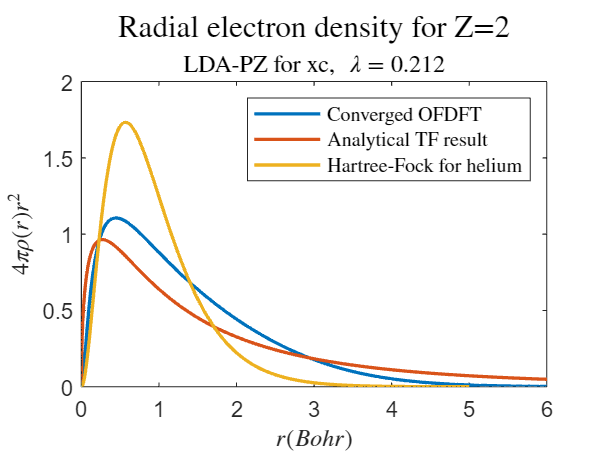

clf;
plot([0;S_OFDFT.r],[0;4*pi*S_OFDFT.rho.*S_OFDFT.r.^2],r_x,4*pi*rho_r_x.*r_x.^2)
xlabel("$r (Bohr)$",Interpreter='latex')
ylabel("$4\pi \rho(r) r^2$",Interpreter='latex')
xlim([0 6])
legend("converged OFDFT","Analytical TF result",Interpreter='latex')
title(['Radial electron density for Z=',num2str(Z)],'Interpreter','latex', fontsize=14)
if xc
    subtitle(['LDA-PZ for xc, \,\, $\lambda=$',num2str(lambda)],Interpreter='latex')
else
    subtitle(['No xc, \,\, $\lambda=$',num2str(lambda)],Interpreter='latex')
end

box on

if Z==1 
    hold on
    syms rh
    fplot(4*rh^2*exp(-2*rh))
    xline(1)
    legend("Converged OFDFT","Analytical TF result","Hydrogen exact",Interpreter='latex')
    hold off
elseif Z==2
    hold on
    load HFrho;
    plot(HFrho.x,HFrho.y)
    legend("Converged OFDFT","Analytical TF result","Hartree-Fock for helium",Interpreter='latex')
    hold off
end

Next, we plot the radial dependence of 

- External potential $V_{\mathrm{ext}}(r )$ 

and of the converged values of (for converged $\rho$):

- The TF potential $V_{\mathrm{TF}}[\rho](r)$ 

- Hartree potential $V_{\mathrm{H}}[\rho](r )$  

- Exchange-correlation potential $V_{\mathrm{xc}}[\rho](r )$ (if selected) 

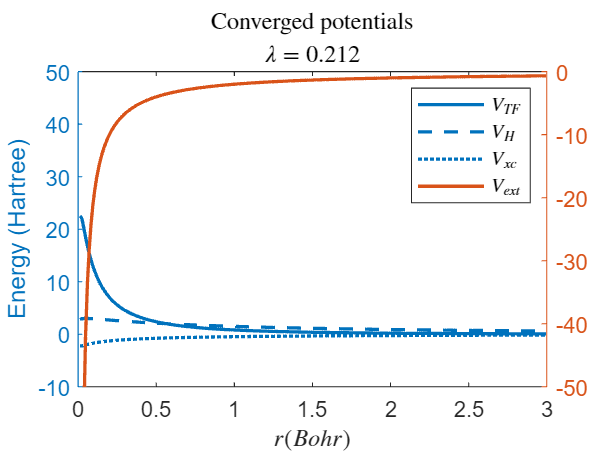

figure
yyaxis left
plot(S_OFDFT.r,S_OFDFT.Vtf,S_OFDFT.r,S_OFDFT.Vh)
if S_OFDFT.xc == 1
    hold on
    plot(S_OFDFT.r,S_OFDFT.Vx+S_OFDFT.Vc);
    hold off
end
ylim([-10 50])
ylabel("Energy (Hartree)")
yyaxis right
plot(S_OFDFT.r,S_OFDFT.Vext)
ylim([-50 0])
if S_OFDFT.xc == 1
    legend("$V_{TF}$","$V_H$","$V_{xc}$","$V_{ext}$",Interpreter='latex')
else
    legend("$V_{TF}$","$V_H$","$V_{ext}$",Interpreter='latex')
end
xlabel("$r (Bohr)$",Interpreter='latex')
xlim([0 3])
title("Converged potentials",Interpreter='latex')
if xc
    subtitle(['$\lambda=$',num2str(lambda)],Interpreter='latex')
else
    subtitle(['No xc, \,\, $\lambda=$',num2str(lambda)],Interpreter='latex')
end
box on
hold off

Next, for the case when xc is activated, we plot separately radial dependence of exchange and correlation potentials to see which contribution is dominant. 

if xc
    figure
    plot( S_OFDFT.r ,S_OFDFT.Vc,S_OFDFT.r,S_OFDFT.Vx)
    legend("$V_{c}$","$V_{x}$",Interpreter='latex')
    xlim([0.2,10])
    ylabel("$V_{x}(r),V_{c}(r) $",Interpreter='latex')
    xlabel("$r$ (Bohr)",'Interpreter','latex')
    title( "Exchange and Correlation Potentials",Interpreter='latex')

And lastly we plot the converged effective potential $V_{\mathrm{eff}}[\rho_{converged}](r)=V_{TF}+V_{\mathrm{ext}}+V_\mathrm{H}+V_{\mathrm{x}}+V_{\mathrm{c}}$

    figure
    plot(S_OFDFT.r,S_OFDFT.Veff)
    xlim([0.2,10])
    ylabel("$V_{eff}\,\,[\rho](r)$",Interpreter='latex')
    xlabel("$r$ (Bohr)",Interpreter='latex')
    title( "Effective Potential",Interpreter='latex')
end

## Simple Numerical Solver for Radial OFDFT

This last section includes numerical solver for radial OFDFT. We start by implementing Hamiltonian ($N_d$x$N_d$ matrix) $\hat \mathcal{H}_r$ times (columnar vector with $N_d$ entries) $u( r)$, instead of implementing directly the Hamiltonian in Eq. (12) $\hat \mathcal{H}_r=-\frac{\lambda}{2} \frac{\partial^2}{\partial r^2} +V_{eff}(r)$ as a matrix. 

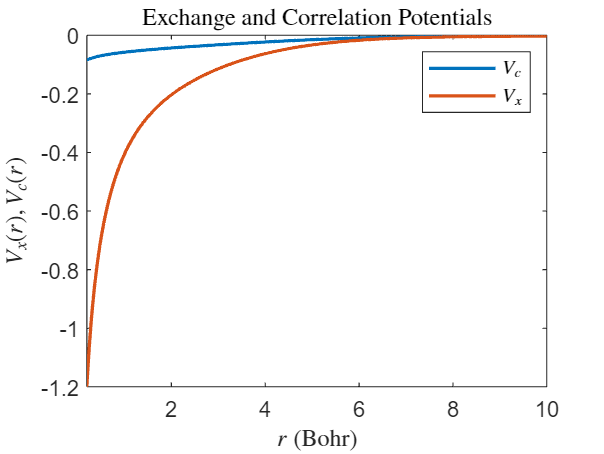

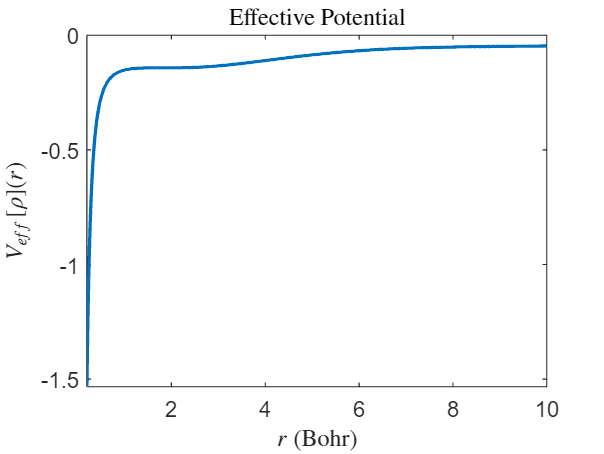

function Hr_u = Hamiltonian(S,u)

% Hamiltonian times vector routine
Hr_u = - S.lambda/2*S.Lap*u + S.Veff.*u;
end

Next we implement the effective potential, with Thomas-Fermi and extrernal potentials given by,


$$\begin{array}{cc}V_{\mathrm{TF}}(r)=\frac{5}{3} C_F \rho^{2/3}(r) = \frac{5}{3} C_F \frac{u^{4/3}(r)}{r^{4/3}}, \quad V_{\mathrm{ext}}(r) = -\frac{Z}{r}, \quad& \qquad (13)\\ \end{array}$$


and Hartree and exchange-correlation potentials obtained from Eqs. (8) (or rather its 1D radial version given in Eq. (14) below) and Eq. (7b) respectively.

function S = compute_effective_potential(S,rho)
% compute effective potential. After S=compute_effective_potential(S,rho) -> structure S 
% picks up additional fields, various potentials, including effective potential. 
    S.Vtf = (5/3)*S.Cf*rho.^(2/3);
    S.Vh = compute_hartree_potential(S,rho);
    S.Veff = S.Vtf + S.Vext + S.Vh;
    if S.xc == 1
        rho(rho < 1e-10) = 1e-10;
        [S.Ex,S.Vx] = slater(rho);
        [S.Ec,S.Vc] = pz(rho);
        % total potential 
        S.Veff = S.Veff + S.Vx + S.Vc;  % complete effective potential when xc is activated
    end
end

By the spherical symmetry of $\rho$, we know that $V_{\mathrm{H}}$ is also spherically symmetric. By introducing $\varphi = rV_{\mathrm{H}}$, the Poisson's equation Eq. (8) for $r>0$ becomes $\frac{1}{r} \frac{\partial^2}{\partial r^2}\varphi(r) = -4\pi\rho(r)$

or,


$$\varphi''(r) = -4\pi r \rho(r). \qquad (14)$$


Using left divide symbol `\` to solve the Eq. (14), avoiding inversing sparse one-dimentional Laplacian $\Delta_{1D}=\frac{\partial^2}{\partial r^2}$, we obtain: $\phi(r) = \triangle_{1D}$ \ $\left(-4\pi \rho(r)r\right)$. 

function Vh = compute_hartree_potential(S,rho)
    
    phi = S.Lap\(-4*pi*rho.*S.r); % note the left divide sign mldivide \ for solving equation (14)
    Vh = phi./S.r;
end

For purely local LDA-PZ xc functional, we also have $V_{\mathrm{xc}}(\mathbf{r}) = V_{\mathrm{xc}}(r)$. We remind that 3D integral of spherically symmetric function $f$ over $\mathbf{R}^3$ in spherical coordinates becomes 1D integral:


$$\begin{array}{cc}\int f(\mathbf{r} ) d \mathbf{r}  = 4\pi \int_0^{\infty} f(r) r^2 dr.& \qquad (15)\\ \end{array}$$
 

function intf = int3d(S,f)
% Computes integral of function in R3 in spherical coordinates assuming f is spherically symmetric
    
    intf = 4*pi*S.h*sum(f.*S.r.^2);
end

Thus, the total energy can be expressed in terms of $u(r)$ :


$$\begin{array}{cc}\begin{array}{rll}E =& T_{\mathrm{TF}} + \lambda T_{\mathrm{vW}}(\rho) + E_{\mathrm{ext}} + E_{\mathrm{xc}} + E_{\mathrm{H}} \\=& 4\pi C_F \int u^{10 / 3}(r)/r^{4/3}d r  - 2 \pi \lambda \int u(r) u''(r) dr \\&- 4\pi \int \frac{Z}{r} u^2(r) dr +  4 \pi \int \epsilon_{\mathrm{xc}}(r) u^2(r) dr + 2 \pi \int V_{\mathrm{H}}(r) u^2(r) dr\end{array}& \qquad (16)\\ \end{array}$$
 

function S = energy(S)
% compute all energies. After S=energy(S) -> structure S picks up additional fields, 
% various energies, including total energy.
    
    S.Ek = S.Cf * int3d(S,S.rho.^(5/3)) - S.lambda/2*int3d(S,S.u.*(S.Lap*S.u)./S.r.^2);
    S.Eh = 0.5*int3d(S,S.Vh.*S.rho);
    S.Eext = int3d(S,S.Vext.*S.rho);
    S.Etot = S.Ek + S.Eh + S.Eext;
    if S.xc == 1
        S.Exc = int3d(S,(S.Ex+S.Ec).*S.rho);
        S.Exchange=int3d(S,S.Ex.*S.rho);
        S.Ecorr=S.Exc-S.Exchange;
        S.Etot = S.Etot + S.Exc;
    end
end

The normalization condition $\int \rho(\mathbf{r}) d\mathbf{r} =4\pi \int \rho(r)r^2 dr=Z$ translates to


$$\begin{array}{cc}4\pi \int u^2(r) dr = Z& \qquad (17)\\ \end{array}$$
 

that we implement numerically after each iteration as follows:

function u = normalize(S,u)
% normalizes u = r * rho^(1/2)
% in order to have the 3D integral of rho equal to Z for a neutral atom
    
    scale = S.Z / (u'*u*4*pi*S.h);   % S.h=dr, integration measure in radial direction
    u = u * sqrt(scale);
    u = abs(u);
end

With the above normalization in Eq. (17), we can calculate the Lagrange multiplier $\mu$ from Eq. (12)


$$\mu = \frac{4\pi}{Z}\int u(r) \hat \mathcal{H}_ru(r) dr \to  \frac{4\pi}{Z} \Delta r \vec u^T \mathcal{H}_{N_dxN_d} \vec u. \qquad (18)}$$


 We used above vector denotions, representing $u(r )$ as an $N_d$-dimensional (columnar) vector $\vec u$ and Hamiltonian $\hat \mathcal{H}_r$ as an $N_d$x$N_d$-dimensional square matrix $\mathcal{H}_{NdxNd}$. $\vec u^T=\{u(r_1),u(r_2),...u(r_{N_d})\}$ is transposed of vector $\vec u$.

function mu = compute_mu(S,u)
    % compute Lagrange multiplier mu
    mu = 4*pi*S.h*(u'*Hamiltonian(S,u)) / S.Z;  % u' is transposed of u, hence is a row vector
end

### Energy Minimization by Nonlinear Conjugate Gradient Method

Eq. (6) and its 1D formulation Eq. (12) constitute nonlinear problems that are hard to be solved directly. A variety of techniques are available for minimizing Lagrangian in Eq. (5). Here we use [nonlinear conjugate gradient](https://en.wikipedia.org/wiki/Nonlinear_conjugate_gradient_method) (NLCG) minimization method with Polak–Ribière implementation. 

Below we sketch the outline of the numerical algorithm we implement. 

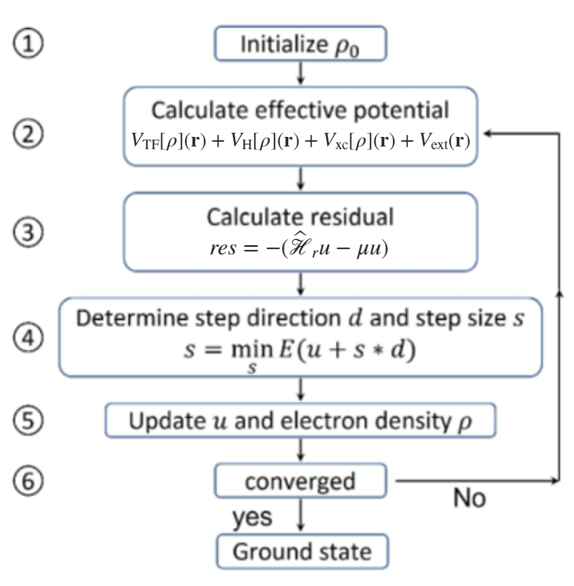

Figure 1: Steps of radial OFDFT.

Below we show how to calculate residual (direction of negative gradient of Lagrangian), determining the direction of the steepest decrease of Lagrangian (see Exercise 4), optimal step size in the direction of the steepest decrease $s$, and what convergence criterium we use to exit the iteration loop.

We start by defining function that initializes the problem.

function S = init_OFDFT(Z,R_MAX,Nd,tol,FDn,lambda,xc,rho0)
    
    S = struct();
    S.Z = Z;
    S.Nd = Nd;
    S.h = R_MAX/(Nd);
    S.r = linspace(S.h,R_MAX,Nd)'; % radial space
    S.FDn = FDn;
    S.tol = tol;
    S.Cf = (3/10)*(3*pi^2)^(2/3);
    S.lambda = lambda;
    S.xc = xc;  % xc=1 means that we are using LDA-PZ exchange-correlation functional
    
    % energy
    S.Etot = 0; % total energy initially set to 0
    
    % external (nuclear) coulomb potential 
    S.Vext = - S.Z./ S.r; 
    
    % Laplacian matrix in 1D
    S.Lap = Laplacian(S.FDn,S.Nd,S.h);

Now we describe each step of our numerical implementation of radial OFDFT,  sketched in Fig. 1.

**Step 1: **Initialize the electron density by using some reasonable guess, and interpolate it using [`griddedInterpolant`](https://www.mathworks.com/help/matlab/ref/griddedinterpolant.html#d126e628453) function. Interpolation is needed due to a mismatch between the mesh of the initial guess and $N_d$ and $R_{max}$ parameters. Here we interpolate $r^2\rho(r)$, which is smoother than $\rho(r)$, by cubic spline interpolation method.

    % initial electron density 
    if nargin == 8 
    % if initial guess of electron density is provided as an 8-th argument of function init_OFDFT
        x = rho0(:,1);
        rho_r = rho0(:,2);
        r2rho = griddedInterpolant(x, x.^2.*rho_r, 'spline');
        r2rho = r2rho(S.r);
        r2rho(S.r>x(end)) = 0; % interpolate to zero density outside of the initial grid used in guess
        rho0 = r2rho ./S.r.^2;
        S.u = normalize(S,S.r.*sqrt(rho0));
        S.rho0 = (S.u./S.r).^2;
        S.rho = S.rho0;
    else  
    % if only first 7 arguments are provided to function init_OFDFT
    % use default 1s electron density as an initial guess
        R = exp(-S.Z*S.r);
        S.u = normalize(S,S.r.*R);
        S.rho0 = (S.u./S.r).^2;
        S.rho = S.rho0;
    end
end

Then we start the nonlinear conjugate gradient algorithm.

function S = NLCG(S)
% Polak–Ribière algorithm for nonlinear conjugate gradient method
    
    % NLCG parameters
    i = 0; 
    imax = 12000; % maximum number of iterations
    tol = S.tol;

**Step 2:** Compute for current (properly normalized) density and $u(r )$: 

- effective potential $V_{eff}[\rho](r)$

- action of the Hamiltonian $\hat \mathcal{H}_r=-\frac{\lambda}{2} \frac{\partial^2}{\partial r^2} +V_{eff}[\rho](r)$ on $u(r )$:  $\mathcal{H}_{N_dxN_d} \vec u$

- the Lagrange multiplier $\mu = \frac{4\pi}{Z}\int u(r) \hat \mathcal{H}_ru(r) dr\to \frac{4\pi}{Z} \Delta r \sum_{i=1}^{N_d} u(r_i) \hat \mathcal{H}_ru(r_i)= \frac{4\pi}{Z} \Delta r \vec u^T \mathcal{H}_{N_dxN_d} \vec u$

 Since it is cheaper to store a vector than to store a matrix, we will store numerically action of the Hamilton matrix on the vector $\vec u$, instead of storing the Hamilton matrix separately.

    S = compute_effective_potential(S,S.rho);
    Hu = Hamiltonian(S,S.u); 
    mu= compute_mu(S,S.u); 

**Step 3:** Compute the residual $res=-(\hat\mathcal{H}_r u-\mu u)$. 

- Note that, after discretizing the radial direction in $N_d$ diescrete sites, $u(r)$ becomes an $N_d$-dimensional (columnar) vector $\vec u=\{  u(r_1), u(r_2),...,u(r_{N_d}) \}$, and so does $\vec {res}$, with components: $res_i=res(r_i)=-\nabla_{u(r_i)} \mathcal{L}/(8\pi \Delta r)=-(\hat \mathcal {H}_r u-\mu u)(r_i)$, where gradient of Lagrangian is taken with respect to the $N_d$-dimensional vector $\vec u$(see Hint to Exercise 4) and $\Delta r=R_{max}/N_d$ is the integration measure in radial direction (stored in `S.h` variable). We are minimizing the Lagrangian $\mathcal{L}$ (see Exercise 5 where reader is sugegsted minimizing directly energy), hence by taking its negative gradient we are finding the direction of its steepest decrease, where the $N_d$-dimensional vector $\vec{res}$ is pointing towards. 

- Note also that due to normalization$\int u^2(r) dr = Z/(4\pi)$, we have $\mu = \frac{4\pi}{Z}\int u(r) \hat \mathcal{H}_ru(r) dr$, and hence $\int u(r) res(r) dr=0$, meaning $(\vec u \cdot \vec{res})=0$, hence $\vec {res}$ points orthogonal to $\vec u$ (there are $N_d-1$ orthogonal directions to a given vector in $N_d$-dimensional space).

- Lastly, note that, our numerical solver keeps normalization of density explicitely, starting from the initial guess and throughout each iteration:$\int u^2(r) dr = Z/(4\pi)$. 

    res = - (Hu - mu * S.u); % columnar vector with Nd components, showing direction of the steepest decrease of Lagrangian 
    d = res;

**Step 4:** Find the step size $s$ minimizing the Lagrangian or equivalently energy given in Eq. (16) (note $\mathcal{L}=E$ for $\int \rho(\mathbf{r}) d\mathbf{r} = N$), using `fminsearch` - multidimensional unconstrained nonlinear minimizer (Nelder-Mead). `X = fminsearch(FUN,X0)` starts at `X0` and attempts to find a local minimizer `X` of the function `FUN`.  

    % determine value of step size in the steepest decrease direction: s
    OFDFTEnergyEvaluator = @(s) ofdft_find_mins(S,S.u,s,d);
    s = fminsearch(OFDFTEnergyEvaluator,0);
    
    S.u = S.u+s*d;          % update u -> u+ s*d
    S.u = normalize(S,S.u); % normalize u according to Eq. (17)
    S.rho = (S.u./S.r).^2;  % rho=u^2/r^2 
    rold = res;
    
    while i < imax

**Repeat Step 2:** Compute effective potential, Hamiltonian times $u$ and chemical potential $\mu$ for the current density.

        S = compute_effective_potential(S,S.rho);
        S = energy(S);
        Hu = Hamiltonian(S,S.u);
        mu = compute_mu(S,S.u);

**Repeat Step 3:** Compute the residual $res=-(\hat\mathcal{H}_r u-\mu u)$.

        res = - (Hu - mu * S.u);
        deltaNew = S.h*sum(res.^2);
    
       % uncomment line below to see results in real-time, after each iteration
       % fprintf(" iter%-5d s %.4f Energy(Ha) %.4f error %.1E\n", i+1,s,S.Etot,deltaNew);

 If $\vec{res}=0$, this means that $u$ is converged (stationary point of Lagrangian is reached, $u$ satisfies the Euler-Lagrange equation $\hat \mathcal{H}_ru=\mu u$) and we are done. Hence, when $\int \vec{res}^2dr$ becomes smaller than predefined tolerance, we will stop the iteration. 

        if deltaNew < tol
            break;
        end

Determine the next searching step direction. This is the Polak–Ribière implementation of NLCG method. The reader is recommended to consult literature on NLCG method and its [Polak–Ribière implementation](https://en.wikipedia.org/wiki/Nonlinear_conjugate_gradient_method).  

        v1 = S.h*sum(rold.*res);
        v2 = S.h*sum(rold.*rold);
    
        eta = (deltaNew - v1) / v2;
        % the search direction needs to be reset to the steepest descent direction time after time
        % resetting every iteration, however, will turn conjugate gradient into steepest descent method 
        if eta <= 0                 
            d = res;  % here direction is reset to steepest descent direction
        else
            d = eta * d + res;
        end

**Repeat Step 4: **Find the step size $s$ minimizing the energy using [`fminsearch`](https://www.mathworks.com/help/matlab/ref/fminsearch.html) function. 

        OFDFTEnergyEvaluator = @(s) ofdft_find_mins(S,S.u,s,d);
        s = fminsearch(OFDFTEnergyEvaluator,0); % starts at the point 0 and attempts to find a local minimum s 
        
        S.u = S.u+s*d;
        S.u = normalize(S,S.u);
        S.rho = (S.u./S.r).^2;
    
        rold = res;
        i = i + 1;
    end
    
    fprintf('Finished NLCG in %d steps with mu = %.4f, err %.2e!\n', i+1,mu,deltaNew);
    fprintf("\nEnergy decomposition \n");
    fprintf("Ek   = %10.6f Ha\n", S.Ek);
    fprintf("Eh   = %10.6f Ha\n", S.Eh);
    if S.xc == 1
        fprintf("Exc  = %10.6f Ha\n", S.Exc);
        fprintf("Ex  = %10.6f Ha\n", S.Exchange);
        fprintf("Ec  = %10.6f Ha\n", S.Ecorr);
    end
    fprintf("Eext = %10.6f Ha\n", S.Eext);
    fprintf("Etot = %10.6f Ha, %10.6f eV\n", S.Etot, S.Etot * 27.2114079527);
end

Function `ofdft_find_mins` that defines energy as function of variables $u(r)$ the update step size $s$ (a scalar) and directon of the steepest decrease $d(r )$: $u_{new}(r)=u_{old}(r) +s\cdot d(r)$. Both $u(r)$ and $d(r)$ are $N_d$-dimensional vectors. 

function [Etot] = ofdft_find_mins(S,u,s,d)
% function that will be used to find optimal step size
    
    u = u + s .* d;
    S.u = normalize(S,u);
    S.rho = (S.u./S.r).^2;
    S = compute_effective_potential(S,S.rho);
    S = energy(S);
    Etot = S.Etot;
end

Below are pair of functions (`slater` and `pz`) for implementing LDA exchange and LDA-PZ correlation functional and potential.

function [ex,vx] = slater(rho)
% slater exchange
    
    % rho, electron density
    % ex, exchange energy density 
    % vx, exchange potential 
    
    C2 = 0.73855876638202; % 3/4*(3/pi)^(1/3)
    C3 = 0.9847450218427;  % (3/pi)^(1/3)
    ex = - C2 * rho.^(1./3.);
    vx = - C3 * rho.^(1./3.);
end

function [ec,vc] = pz(rho)
% pz correlation: Perdew-Zunger implementation of LDA correlation energy and potential
    
    % rho, electron density
    % ec, correlation energy density 
    % vc, correlation potential
    
    A = 0.0311;
    B = -0.048;
    C = 0.002;
    D = -0.0116;
    gamma1 = -0.1423;
    beta1 = 1.0529;
    beta2 = 0.3334;
    
    % compuatation
    ec = zeros(size(rho,1),1);
    vc = zeros(size(rho,1),1);
    rs = (0.75./(pi*rho)).^(1.0/3.0) ;
    islt1 = (rs < 1.0);
    lnrs = log(rs(islt1));
    sqrtrs = sqrt(rs(~islt1));
    ec(islt1) = A * lnrs + B + C * rs(islt1) .* lnrs + D * rs(islt1);
    ox = 1.0 + beta1*sqrtrs + beta2*rs(~islt1);
    ec(~islt1) = gamma1 ./ ox;
    vc(islt1) = lnrs.*(A + (2.0/3.0)*C*rs(islt1)) + (B-(1.0/3.0)*A) + (1.0/3.0)*(2.0*D-C)* rs(islt1);
    vc(~islt1) = ec(~islt1) .* (1 + (7.0/6.0)*beta1*sqrtrs + (4.0/3.0)*beta2*rs(~islt1)) ./ ox;
end

Finally, we provide functions for creating discrete Laplacian using central finite difference method. See more information at [https://en.wikipedia.org/wiki/Finite_difference_coefficient](https://en.wikipedia.org/wiki/Finite_difference_coefficient).

%%%%%%% finite difference functions %%%%%%%

function Lap = Laplacian(FDn,Nd,h)
% the sparse 1D Laplacian matrix 
    
    % FDn, half order of accuracy
    % Nd, number of grid points
    % h, mesh 
    
    w2 = w2_c(FDn);
    e = ones(Nd,1)/h^2;
    Lap = spdiags(w2(1)*e,0,Nd,Nd);
    for i = 1:FDn
        Lap = Lap + spdiags(w2(i+1)*e,i,Nd,Nd);
        Lap = Lap + spdiags(w2(i+1)*e,-i,Nd,Nd);
    end
end

function w2 = w2_c(FDn)
% generate central finite difference coefficients for second order derivative
    
    % FDn, half order of accuracy
    % w2, central finite difference coefficients
    
    w2 = zeros(1,FDn+1) ;
    for k=1:FDn
	    w2(k+1) = (2*(-1)^(k+1))*(factorial(FDn)^2)/...
		    (k*k*factorial(FDn-k)*factorial(FDn+k));
	    w2(1) = w2(1)-2*(1/(k*k));
    end
end

## ** Exercises**

**Exercise 1: **Using the definition of Hartree potential $V_{\mathrm{H}}[\rho](\mathbf{r}) = \displaystyle\int  \frac{\rho\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|}d \mathbf{r}^{\prime}$, in case spherically symmetric charge distribution, when $\rho(\mathbf{r})=\rho(r )$, show that Hartree potential also has spherical symmetry $V_H[\rho](\mathbf{r})=V_H[\rho](r)$. 

Hint: To simplify calculations orient the coordinate system so that the z axis is directed along the $\mathbf{r}$ vector. Then angle between $\mathbf{r'}$ and $\mathbf{r}$ vectors will be $\theta'$. Calculate the distance $|\mathbf{r}-\mathbf{r'}|$ in this system, remembering that distance does not depend on orientation of the coordinate system. Passing to spherical coordinates, out of 3 integration variables (spherical coordinates of $\mathbf{r'}$), integrate over $\theta'$ first (see live script on *Hartree Method*), using 


$$\int_0^{\pi} \frac{\sin{\theta'}}{|\mathbf{r'}-\mathbf{r}|} \mathrm{d} \theta' =  \begin{cases} 2/r,& \text{if } r\geq r'\\ 2/r' , &  \text{if }  r<r' \end{cases}$$


 to obtain: 


$$V_{\mathrm{H}}[\rho] (\mathbf{r}) =  \frac{4\pi}{r} \int_{0}^{r}   \rho(r') r' \,^2dr'+4\pi \int _{r}^{\infty} \rho(r')r'  dr'=V_{\mathrm{H}}[\rho] (r).$$


**Exercise 2: **Consider $Z=1$ and $Z=2$ atoms.  Put $\lambda=\epsilon_{xc}=0$, $R_{max}=60/Z^{1/3}$, `tol=`$10^{-6}$ and calculate ground state energies for $N_d=n\cdot 30,000$ for $n=1,2,..10$. Using curve fitting app and FIT TYPE Custom Equation: $E_0^{N_d}(Z) = E_0^{\infty}(Z) +b(Z)/ \sqrt{N_d}$ determine $E_0^{\infty}(Z)$ and compare results with the Thomas-Fermi expression $E^{TF}_0(Z)=-0.7687Z^{7/3}$.

Hint: Uncomment line below to call curve fitting app. Create two vectors `x=3e4:3e4:3e5 and` `y=E_0(x)` and select them from the app.

% curveFitter

**Exercise 3: **For $\lambda=0.212$, `xc=lda`, `tol=`$10^{-3}$, $N_d=1000$, and $R_{max}=60/Z^{1/3}$calculate ground state energy for atoms with $Z=20, 30, 40, 50, 60$ and using curve fitting app fit the result to $E_0(Z)=-const\cdot Z^{7/3}$. Determine value of $const$. For larger values of $Z$ maximum number of iteration steps should be increased to achieve convergence to a desired accuracy (alternatively $N_d$ can be decreased however at the expence of increasing finite-size error).

**Exercise 4:** Suppose $f$ is a scalar differentiable function defined on $R^n$. Show that direction of the steepest decrease of the function $f$ at point $\vec x \in R^n$ is $-\nabla f(\vec x)=-\displaystyle\sum_{i=1}^n\vec e_{x_i}\partial_ {x_i }f(\vec x)$. 

Hint: take $\vec y \in R^n$ such that $|\vec y|=\varepsilon\to 0$ and calculate $f(\vec x +\vec y)=f(\vec x)+ \varepsilon | \nabla f(\vec x)|\cos{\alpha_{( \mathbf{x} ,\mathbf{y})}}+O(\varepsilon^2)$, where $\alpha_{(\mathbf{x},\mathbf{y} )}$ is an angle between vectors $\vec x$ and $\vec {y}$. Then, among all vectors with length $\varepsilon$, $f(\vec x+\vec y)$ achieves minimal value if $\alpha_{(\mathbf{x},\mathbf{y} )}=\pi$, hence $\vec y$ is antiparallel to $\nabla f(\vec x)$.

When we are minimizing Lagrangian, we have the following identification: $n\to N_d$, $x_i \to u_i= u(r_i)$ and $f\to\mathcal{L}$.

**Exercise 5: **When implementing NLCG method, put $\mu=0$ and define residue $res$ as a direction of the negative gradient of energy given in Eq. (16): $res(r_i)=-\nabla_{u(r_i)} E/(8\pi \Delta r)$, hence and $res=-\hat\mathcal{H}_ru$. Check how results for ground state energy and ground state electron density change for $Z=2,3,4,...$. and observe what happens to convergence properties of the modified numerical algorithm.

**Exercise 6: **Take converged radial Hamiltonian $\hat \mathcal{H}_r=-\frac{\lambda}{2} \frac{\partial^2}{\partial r^2} +V_{eff}[\rho_{converged}](r)$ and check that Eq. (12) $\hat\mathcal{H}_r u(r)=\mu u(r)$, that is a radial version of Eq. (6), has a unique physically acceptable (nodeless, hence can be chosen as everywhere positive $u(r)\ge 0$) solution.

Hint: consider small system sizes up to $N_d=800$. Then after running the script create a sparse Hamilton matrix: 

>>Hr = sparse(-S_OFDFT.lambda/2*S_OFDFT.Lap + diag(S_OFDFT.Veff));

Then obtain its $3$ lowest eigen values and corresponding eigen vectors. The lowest eigen value is chemical potential $\mu$.

`>>[V,D]=eigs(Hr,3,'smallestreal');`

Then plot each eigen vector, say the lowest one

`>>plot(S_OFDFT.r,-V(:,1))`

Finally compare the lowest eigen vector with the converged $u(r)$

`>>plot(S_OFDFT.r,-V(:,1),S_OFDFT.r,S_OFDFT.u*sqrt(4*pi*S_OFDFT.h/S_OFDFT.Z))`

**Exercise 7: **Instead of implementing NLCG method, for small system sizes, up to $N_d=800$, directly solve iteratively Eq. (12) $\hat\mathcal{H}_r [\rho]u(r)=\mu u(r)$, $\rho(r)=u^2(r)/r^2$, starting from the Thomas-Fermi initial electron density.

Hint: Implement the iterative non-linear eigen problem solver as indicated below. It is important to implement density-mixing scheme (similar to one that we use in Kohn-Sham implementation of DFT), to avoid numerically challenging large density redistributions that occur from iteration to iteration.

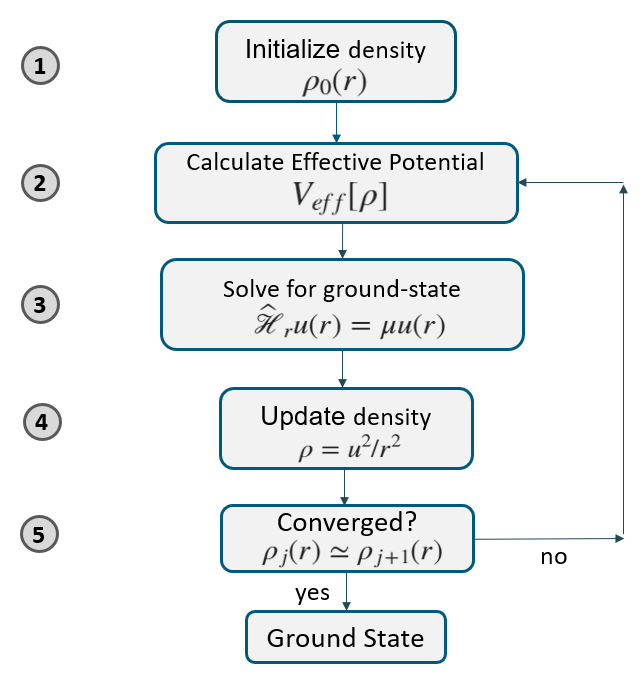

Below is a naive version, without checking for convergence criterium.

 `>> j=0;`

`    jmax = 200; % maximum number of iterations`

`    S = compute_effective_potential(S,S.rho); `

`    opts = struct(maxit=5000, tol= S.tol, isreal=1);`

`    beta=0.95; % density mixing parameter`

`    while j < jmax`

`        Hfun = @(x) Hamiltonian(S,x);  `

`        [S.u, mu] = eigs(Hfun, S.Nd, 1, 'smallestreal', opts);`

`        S.u = normalize(S,S.u);`

`        S.rho = (1-beta)*(S.u./S.r).^2+beta*S.rho;`

`        S = compute_effective_potential(S,S.rho);`

`        S = energy(S);`

`        j = j + 1;`

`    end`

## References

1. J. P. Perdew and A. Zunger, [*Self-interaction correction to density-functional approximations for many-electron systems*](https://journals.aps.org/prb/pdf/10.1103/PhysRevB.23.5048)*,* Phys. Rev. B **23**, 5048 (1981).

2.  K. Yonei and Y. Tomishima, *On the Weizsäcker correction to the Thomas-Fermi theory of the atom*, J. Phys. Soc. Japan **20**, 1051–1057 (1965). 

3. [Kieron Burke and Friends](https://dft.uci.edu/doc/g1.pdf), *The ABC of DFT*, Department of Chemistry, University of California, Irvine.

4.  S. Ghosh and P. Suryanarayana, *Higher-order finite-difference formulation of periodic orbital-free density functional theory,* Journal of Computational Physics **307**, 634 (2016).

*5. *R. G. Parr and W. Yang, *Density-Functional Theory of Atoms and Molecules*, Oxford University Press, (1995).

6. Wang, Y.A., Carter, E.A. (2002). *Orbital-Free Kinetic-Energy Density Functional Theory*. In: Schwartz, S.D. (eds) Theoretical Methods in Condensed Phase Chemistry. Progress in Theoretical Chemistry and Physics, vol 5. Springer, Dordrecht. [https://doi.org/10.1007/0-306-46949-9_5](https://doi.org/10.1007/0-306-46949-9_5)

7. J. Nocedal, S.J. Wright, *Numerical Optimization*, Springer Series in Operations Research, Springer, New York (1999).